# Projeto de Controle Avançado - Segway

## Tarefa 1

### Item 1 - Modelo Linearizado: Espaço de Estados

    A partir da linearização do modelo completo, somos capazes de determinar as matrizes $A, B, C, D$ necessárias para a modelagem em State Space, que é facilmente feita no matlab através do comando SS.

    Para uma primeira análise, supomos que a única saída que conseguimos mensurar do nosso sistema é o ângulo $q_2$. 

% Clear all old data to avoid data runs
clear;
load controller

% Problem COnstants
mc = 1.5;  % [Kg]
mp = 0.5;  % [Kg]
g = 9.82;  % [m/s^2]
L = 1;     % [m]
d1 = 0.01; % [m]
d2 = d1;   % [m]

% Linearized Plant on State Space format
A = [0,   0,   1,    0;
     0,   0,   0,    1;
     0,   g*mp/mc,   -d1/mc, -d2/(L*mc);
     0,   g*(mc+mp)/(L*mc),  -d1/(L*mc), -d2*(mc+mp)/(L^2*mc*mp)];
 
B = [ 0; 0; 1/mc;  1/(L*mc)];

C = [0 1 0 0];
 
D = 0;

% System object creation
sys = ss(A,B,C,D)


sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


### Item 2 - Análise de Polos e Zeros: Sistema 1

    A partir do modelo em espaço estados, somos capzes de determinar inúmeras características importantes, sendo as principais se o sistema é Estável (através da análise dos seus polos) mas também se o sistema é de fase mínima ou não (através da análise dos seus zeros).

    Para tal análise podemos utilizar os comandos `pole` e `eig` do matlab.

polos_sys1 = eig(sys)

polos_sys1 =    -3.6327
    3.6043
   -0.0050
         0


zeros_sys1 = zero(sys)

zeros_sys1 = 1.0e-16 *

    0.2931
         0


    Onde podemos observar que o sistema não é estável devido a um dos seus polos estar localizado no semi-plano direito (i.e serem positivos), além de ser um sistema de fase não mínima.

    Outra possível representação para o nosso sistema (que possui somente uma saída observável e uma entrada) é através de uma função de transferência SISO através do comando `ss2tf`:

[num,den] = ss2tf(A,B,C,D);
tf_sys1 = tf(num, den)


tf_sys1 =
 
    0.6667 s^2 - 3.538e-18 s - 5.187e-16
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties


Zerando os polos e zeros que tendem a zero, obtemos uma nova função transferência:

polos_sys1(abs(polos_sys1)<0.01) = 0;
zeros_sys1(abs(zeros_sys1)<0.01) = 0;

[mag, ~, ~] = bode(sys);
[num, denom] = zp2tf(zeros_sys1,polos_sys1, 1);
tf_reduzida = tf(num, denom)


tf_reduzida =
 
               s^2
  -----------------------------
  s^4 + 0.02833 s^3 - 13.09 s^2
 
Continuous-time transfer function.
Model Properties


Podemos observar que houve redução da ordem do sistema ao aproximarmos os polos e zeros muito pequenos a zero:


$$\frac{1}{  s^2 + 0.02833 s - 13.09 }
$$


Onde isso ocorre pois ao zerarmos os polos e zeros próximos chegamos em um sistema onde 2 zeros e dois polos são iguais a zero, a partir da onde eles se cancelam, reduzindo a ordem do sistema.

### Item 3 - Análise de Polos e Zeros: Sistema 2

Supondo uma variação do sistema, agora onde o estado observado é o $q_1$, onde sua representação em espaço estado é:

C = [1 0 0 0];
sys_2 = ss(A, B, C, D)


sys_2 =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Ou ainda onde sua representação em função de transferência seja:

[num,den] = ss2tf(A,B,C,D);
tf(num, den)


ans =
 
       0.6667 s^2 + 0.01333 s - 6.547
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties


Que possui os seguintes  polos e zeros:

pole(sys_2)

ans =          0
   -3.6327
    3.6043
   -0.0050


zero(sys_2)

ans =     3.1237
   -3.1437


### Item 4 - Comparação: Sistema 1 e Sistema 2

Ao compararmos os zeros de ambos os sistemas, podemos ver que eles são iguais, e isso se da ao fato dos polos descreverem a dinâmica e estabilidade do sistema como um todo, enquanto os zeros diferem consideravelmente entre o sistema com o estado observado sendo $q_1$ e o sistema com o estado observado sendo $q_2$, o que faz sentido se pensarmos que ao analizarmos se um sistema é de fase mínima (para um estado de saída específico) olhamos as naturezas dos zeros.

Matematicamente essa relação pode ser mais claramente observada quando olhamos como a transformação de Espaço Estados para Função de Transferência é feita:


$$H(s) = C(sI - A)^{-1}B + D$$
 

A partir da onde podemos observar que os polos (i.e as raizes do polinomio característico) da função transferência resultante é dada a partir dos autovalores de A, o que pode ser verificado quando comparamos os polos do sistema com os autovalores de A:

eig(A)

ans =          0
   -3.6327
    3.6043
   -0.0050


pole(sys)

ans =    -3.6327
    3.6043
   -0.0050
         0


Sendo que a matriz $A$ é identica para ambos os sisteas.

## Tarefa 2

### Item 1/2: Possíveis Controladores - Sistema 1

A fim de determinar se o controlador mais simples possível, o proporcional puro "$P$" seria capaz de controlar o sistema que atualmente é instável, podemos analisar o seu root locus plot, para entendermos as tendências do sistema para o aumento de ganho:

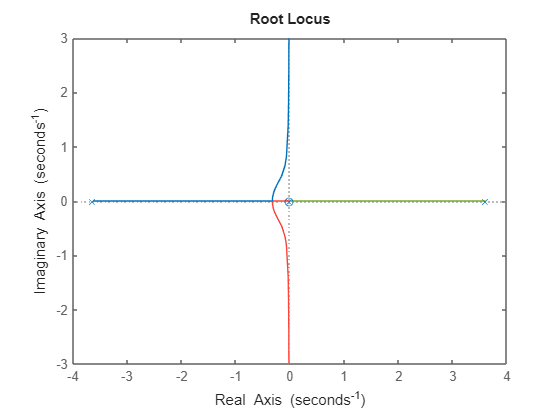

rlocus(sys)

    Onde podemos ver que, através de um ganho $K$ grande o suficiente, o sistema tem a tendência de ser marginlamente estável (i.e o polo que antes estava no semi-plano direito está em agora em zero) mas em contra partida os dois outros polos estão na parte imaginária, o que induz oscilações e overshoot para o sistema, mas ainda assim marginalmente estável. 

    Na prática, entretanto, esse controle seria considerado não válido e possivelmente perigoso, logo seria necessário um controle que possivelmente cancelasse o polo no semi-plano direito e ainda o que está originalmente no zero, ou pelo menos um que cancelasse as oscilações (i.e com par de zeros imaginários).

### Item 3: Design do Controlador

    Utilizando o Siso Tool chegamos em um controlador com um intergador, um polo e um par de zeros complexos:

C_siso


C_siso =
 
  11291 (s^2 + 2.525s + 4.428)
  ----------------------------
           s (s+100)
 
Name: C
Continuous-time zero/pole/gain model.
Model Properties


    Que resulta na seguinte resposta ao degrau:

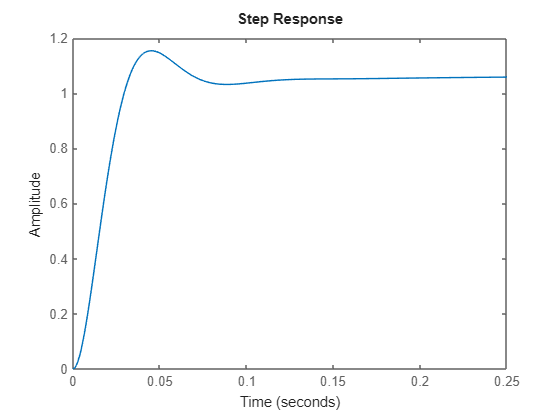

step(feedback(C_siso*sys, 1))

    E possui, em malha aberta, o seguinte root locus map:

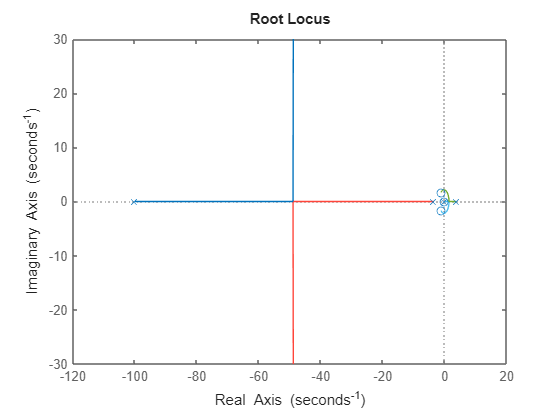

rlocus(sys*C_siso)

### Item 4: Performace do Controlador

    Inicialmente, quando colocamos o controlador em conjunto com o sistema liearizado no simulink, parece que o controle tem uma performance suficiente:

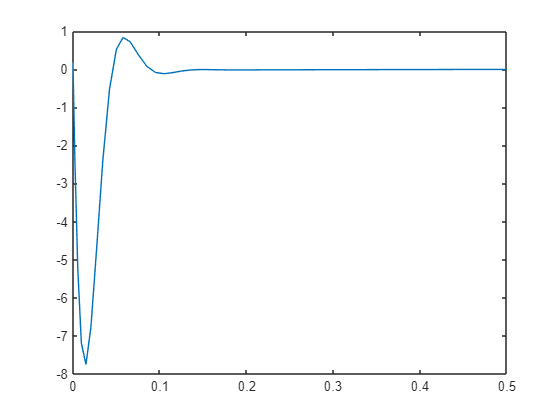

mdl = 'liearized_model.slx';
simulation = Simulink.SimulationInput(mdl);
simulation = simulation.setModelParameter('StopTime', '0.5');

output = sim(simulation);
plot(output.tout, output.logsout{2}.Values.Data)

    Sendo que o comportamento acima está condizente com um sistema estabilizado de fase não mínima, que teve condição inicial $q_2 = 10^\circ$.

 Quando analizamos todos os outros estados para um $t$ simulado suficientemente grande ($t=100s$) podemos ver que a posição $q_1$ não tende a zero:

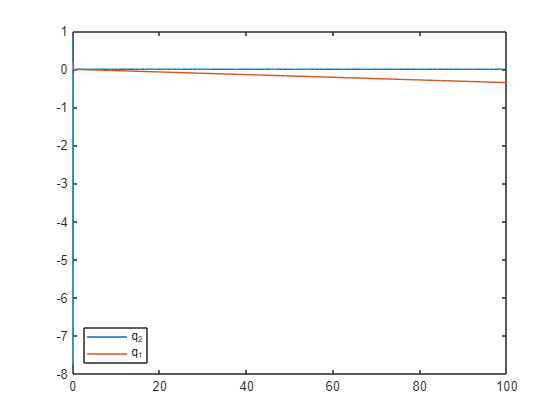

simulation = Simulink.SimulationInput(mdl);
simulation = simulation.setModelParameter('StopTime', '100');

output = sim(simulation);
plot(output.tout, output.logsout{2}.Values.Data), hold on;
plot(output.tout, output.logsout{1}.Values.Data), hold off;
legend('q_2', 'q_1', Location='southwest');

    Para mudar isso, precisamos passar para o design de um full state feedback controller, i.e um controle capaz de atuar em cima de todos os estados de um sistema.

## Tarefa 3

### Item 1: Análise de Observabilidade e Controlabilidade

    Como vimos que um controle siso não é suficiente para convergir todos os estados para zero, é necessário passarmos para um sistema de controle de realimentação de estados. 

    Para isso, entretanto, precisamos primeiro ver se os sistemas são controlaveis e em seguida observáveis:

con_sys1 = ctrb(A, B);
rank(con_sys1)

ans = 4

    Onde podemos ver que, por ser rank cheio, o sistema, independente de qual estado está sendo observado, é controlável através da entrada $u$.

    Já para a análise de observabilidade:

rank(obsv(sys))

ans = 3

rank(obsv(sys_2))

ans = 4

    Podemos ver que para o primeiro sistema (com a saída como sendo $q_2$) a planta não é observável, enquanto para a saída $q_1$ o sistema é observável.

### Item 2: Pole Placement - Sistema 1

Para calcularmos o ganho $K$, podemos utilizar o comando `place` do matlab para calcula-lo de uma forma que os polos em malha fechada seja um específico. Para um primeiro exemplo, tentamos botar os polos:

eigs = [-1 -2 -0.5 -0.1];
K = place(A, B, eigs)

K =    -0.0153   25.4344   -0.2162    5.5662


eig(A-B*K)

ans =    -2.0000
   -1.0000
   -0.5000
   -0.1000


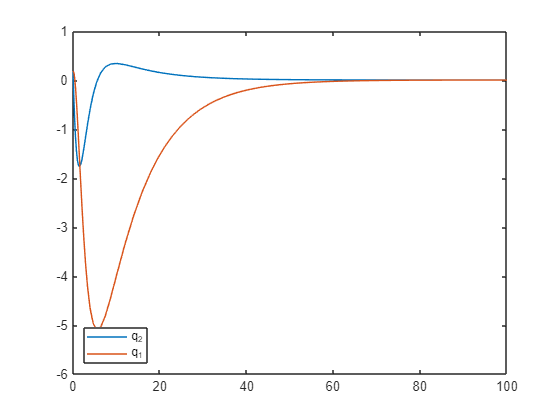

mdl = 'full_state_linearized_model.slx';
simulation = Simulink.SimulationInput(mdl);
simulation = simulation.setModelParameter('StopTime', '100');
simulation = simulation.setBlockParameter('full_state_linearized_model/control_gain','Gain', 'K');

output = sim(simulation);
plot(output.tout, output.logsout{2}.Values.Data), hold on;
plot(output.tout, output.logsout{1}.Values.Data), hold off;
legend('q_2', 'q_1', Location='southwest');

### Item 3: Pole Placement Alternativo - Sistema 1

    Podemos, ainda, botar os polos mais para a esquerda de forma que a resposta seja mais agressiva:

eigs = [-10 -5 -1 -0.5];
K = place(A, B, eigs)

K =    -3.8187  133.2109  -12.6196   37.3196


eig(A-B*K)

ans =   -10.0000
   -5.0000
   -1.0000
   -0.5000


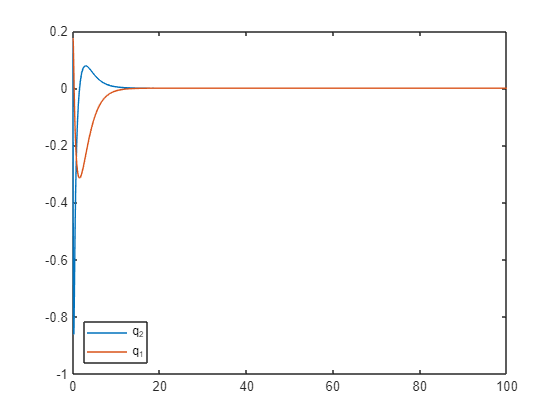

mdl = 'full_state_linearized_model.slx';
simulation = Simulink.SimulationInput(mdl);
simulation = simulation.setModelParameter('StopTime', '100');
simulation = simulation.setBlockParameter('full_state_linearized_model/control_gain','Gain', 'K');

output = sim(simulation);
plot(output.tout, output.logsout{2}.Values.Data), hold on;
plot(output.tout, output.logsout{1}.Values.Data), hold off;
legend('q_2', 'q_1', Location='southwest');

    Onde podemos ver que a resposta transitória é muito mais curta.

### Item 4: LQR - Sistema 1

    Em um primeiro momento, queremos desenvolver um controle que penalize fortemente erros em theta, de forma menos severa x e igualmente as suas respectivas derivadas. Além disso, temos que esforço de controle para o nosso sistema não precisa ser penalizado tão severamente.

    Para o LQR, podemos traduzir esses requisitos para as matrizes $Q$ e $R$:

Q = zeros(4,4);
Q(1,1) = 2;
Q(2,2) = 4;
Q(3,3) = 1;
Q(4,4) = 1;

R = 0.5;

K_lqr = lqr(A, B, Q, R)

K_lqr =    -2.0000   60.6609   -4.3354   17.6916


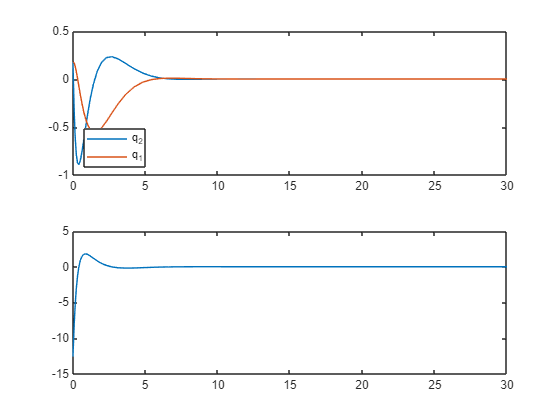

mdl = 'full_state_linearized_model.slx';
simulation = Simulink.SimulationInput(mdl);
simulation = simulation.setModelParameter('StopTime', '30');
simulation = simulation.setBlockParameter('full_state_linearized_model/control_gain','Gain', 'K_lqr');

output = sim(simulation);
subplot(2, 1, 1);
plot(output.tout, output.logsout{2}.Values.Data), hold on;
plot(output.tout, output.logsout{1}.Values.Data), hold off;
legend('q_2', 'q_1', Location='southwest');

subplot(2, 1, 2);
plot(output.tout, output.logsout{5}.Values.Data);

    Alterando, agora, a matriz $R$ de tal forma que temos um custo alto para o esforço do atuador para vermos as diferença que isso causa na resposta do sistema, em conjunto com um peso menor para os erros:

R = 100;

K_lqr = lqr(A, B, Q, R)

K_lqr =    -0.1414   43.6687   -0.8480   12.2240


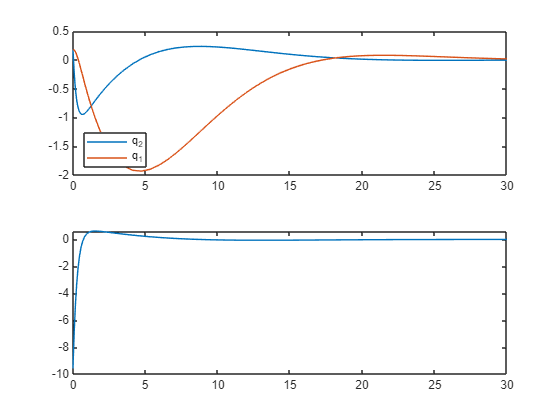

mdl = 'full_state_linearized_model.slx';
simulation = Simulink.SimulationInput(mdl);
simulation = simulation.setModelParameter('StopTime', '30');
simulation = simulation.setBlockParameter('full_state_linearized_model/control_gain','Gain', 'K_lqr');

output = sim(simulation);
clf;
subplot(2, 1, 1);
plot(output.tout, output.logsout{2}.Values.Data), hold on;
plot(output.tout, output.logsout{1}.Values.Data), hold off;
legend('q_2', 'q_1', Location='southwest');

subplot(2, 1, 2);
plot(output.tout, output.logsout{5}.Values.Data);

    Onde podemos ver que o sistema demora mais para estabilizar e os comandos do atuador são menores em módulo para esse segundo controlador.

### Item 6: LQR - Gain Scheduling 

    Uma possibilidade de garantir uma performance adequada do controlador em todo o envelope de operação do sistema é através do uso de gain scheduling, que nada mais é do que determinar os gasnhos K em diferentes pontos.

    Para isso, entretanto, precisamos linearizar o sistema em diferentes pontos de operação:

% syms m_c m_p L q_1 q_dot_1 q_2 q_dot_2 d_1 d_2 g;
% 
% % Nonlinear System
% M = [ m_c+m_p -L*m_p*cos(q_2)
%      -L*m_p*cos(q_2) L^2*m_p];
% 
% h = [L*m_p*q_dot_2^2*sin(q_2)+d_1*q_dot_1
%     -L*g*m_p*sin(q_2)+d_2*q_dot_2];
% 
% % Nonlinear State Space
% F = [q_dot_1; q_dot_2; -1*inv(M)*h];
% 
% G = [0; 0; inv(M)*[1;0]];
% 
% % Linearized System
% A = jacobian(F, [q_1 q_2 q_dot_1 q_dot_2]);

    A partir desseas equações podemos linearizar e calcular os novos valores do K utilizando LQR para cada 10 graus:

% mc = 1.5;  % [Kg]
% mp = 0.5;  % [Kg]
% g = 9.82;  % [m/s^2]
% L = 1;     % [m]
% d1 = 0.01; % [m]
% d2 = d1; 
% for angle = -90:10:90
%     A_linearizado = subs(A, [m_c m_p g d_1 d_2 q_1 q_1])
% end

## Tarefa 4

    Como vimos na análise de controlabilidade e observabilidade do nosso sistema, se tivermos como saída $q_1$ o nosso sistema é observável, logo é possível utilizarmos um observador em conjunto com o controle de realimentação de estados. 

    A primeira coisa que precisamos fazer, portanto, é determinar onde estão os polos do sistema + controlador, tendo em vista que o observador precisa ser entre 3-6 vezes mais rapido:

K_lqr = [-2.0000 60.6609 -4.3354 17.6916];
control_loop_poles = eig(A-B*K_lqr)

control_loop_poles =   -4.0974 + 0.0000i
  -3.2634 + 0.0000i
  -0.7883 + 0.5981i
  -0.7883 - 0.5981i


    Logo iremos querer um observador que possua polos 6 vezes mais rápidos, i.e 6 vezes maiores (mais para dentro do semi-plano esquerdo, i.e mais negativos):

target_observer_poles = control_loop_poles*6

target_observer_poles =  -24.5842 + 0.0000i
 -19.5804 + 0.0000i
  -4.7301 + 3.5886i
  -4.7301 - 3.5886i


C = [1 0 0 0];
K_L = place(A', C', target_observer_poles)'

K_L = 1.0e+03 *

    0.0536
    2.0918
    0.9457
    8.9680


    Que podemos observar ao vermos os autovalores do observador:

eig(A-K_L*C)

ans =  -24.5842 + 0.0000i
 -19.5804 + 0.0000i
  -4.7301 + 3.5886i
  -4.7301 - 3.5886i


    Por fim temos o nosso observador como sendo o seguinte sistema, que possui como entradas tanto $y$ como os comandos $u$:

full_state_observer = ss(A-K_L*C, [B K_L], eye(4), 0*[B K_L])


full_state_observer =
 
  A = 
              x1         x2         x3         x4
   x1     -53.59          0          1          0
   x2      -2092          0          0          1
   x3     -945.7      3.273  -0.006667  -0.006667
   x4      -8968      13.09  -0.006667   -0.02667
 
  B = 
           u1      u2
   x1       0   53.59
   x2       0    2092
   x3  0.6667   945.7
   x4  0.6667    8968
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.
